clc;clear;
close all
load S19_DTSSfit

## Section 1: Controllability and observability

Check the size of the discrete time state space system.

size(dtss_fit)

State-space model with 2 outputs, 2 inputs, and 6 states.


Check controllability.

Q = ctrb(dtss_fit);
controllability = rank(Q)

controllability = 6

rank(Q) = N = 6 <--> Completely controllable

Check observability.

R = obsv(dtss_fit);
observability = rank(R)

observability = 6

rank(R) = N = 6 <--> Completely observable

## Section 2: LQR

Construct the state weighting matrix Q.

Q is N by N.

q = 1;
Q = q * transpose(dtss_fit.C) * dtss_fit.C;

Construct the control effort weighting matrix R.

R is M by M.

R = 1E-1*diag([0.9 0.8]);
G = lqr(dtss_fit,Q,R);

Build sampling informatoin.

Fs = 20;  % Sample rate (Hz)
Ts = 1/Fs; % Sample period (s)
T = 8; % Total period of data
N = T / Ts; % Total number of sampels
F = Fs / N; % frequency resolution
t = 0:Ts:T; % Time vector

Simulate the first second with constant control input.

T1 = 1; % total period of data up to 1s
N1 = T1 / Ts; % total number of data for the second

u1 = 5;
u2 = -5;
x = []; y = []; u = [];
x(:,1) = zeros(6,1);
y(:,1) = zeros(1,2);

for k = 1:N1
    u(:,k) = [u1; u2];
    x(:,k + 1) = dtss_fit.A * x(:,k) + dtss_fit.B * u(:,k);
    y(:,k + 1) = dtss_fit.c * x(:,k) + dtss_fit.D * u(:,k);
end


Simulate the last 7 second with LRQ full state feedback.

T2 = 8; % total period of data up to 8 second
N2 = T2 / Ts; % total number of data

for k = (N1+1):N2
    u(:,k) = - G * x(:,k);
    x(:,k + 1) = dtss_fit.A * x(:,k) + dtss_fit.B * u(:,k);
    y(:,k + 1) = dtss_fit.c * x(:,k) + dtss_fit.D * u(:,k);
end
u(:,k + 1) = - G * x(:,k + 1);

## Section 3

Plot the simulated closed loop time reponse with outputs and control inputs.

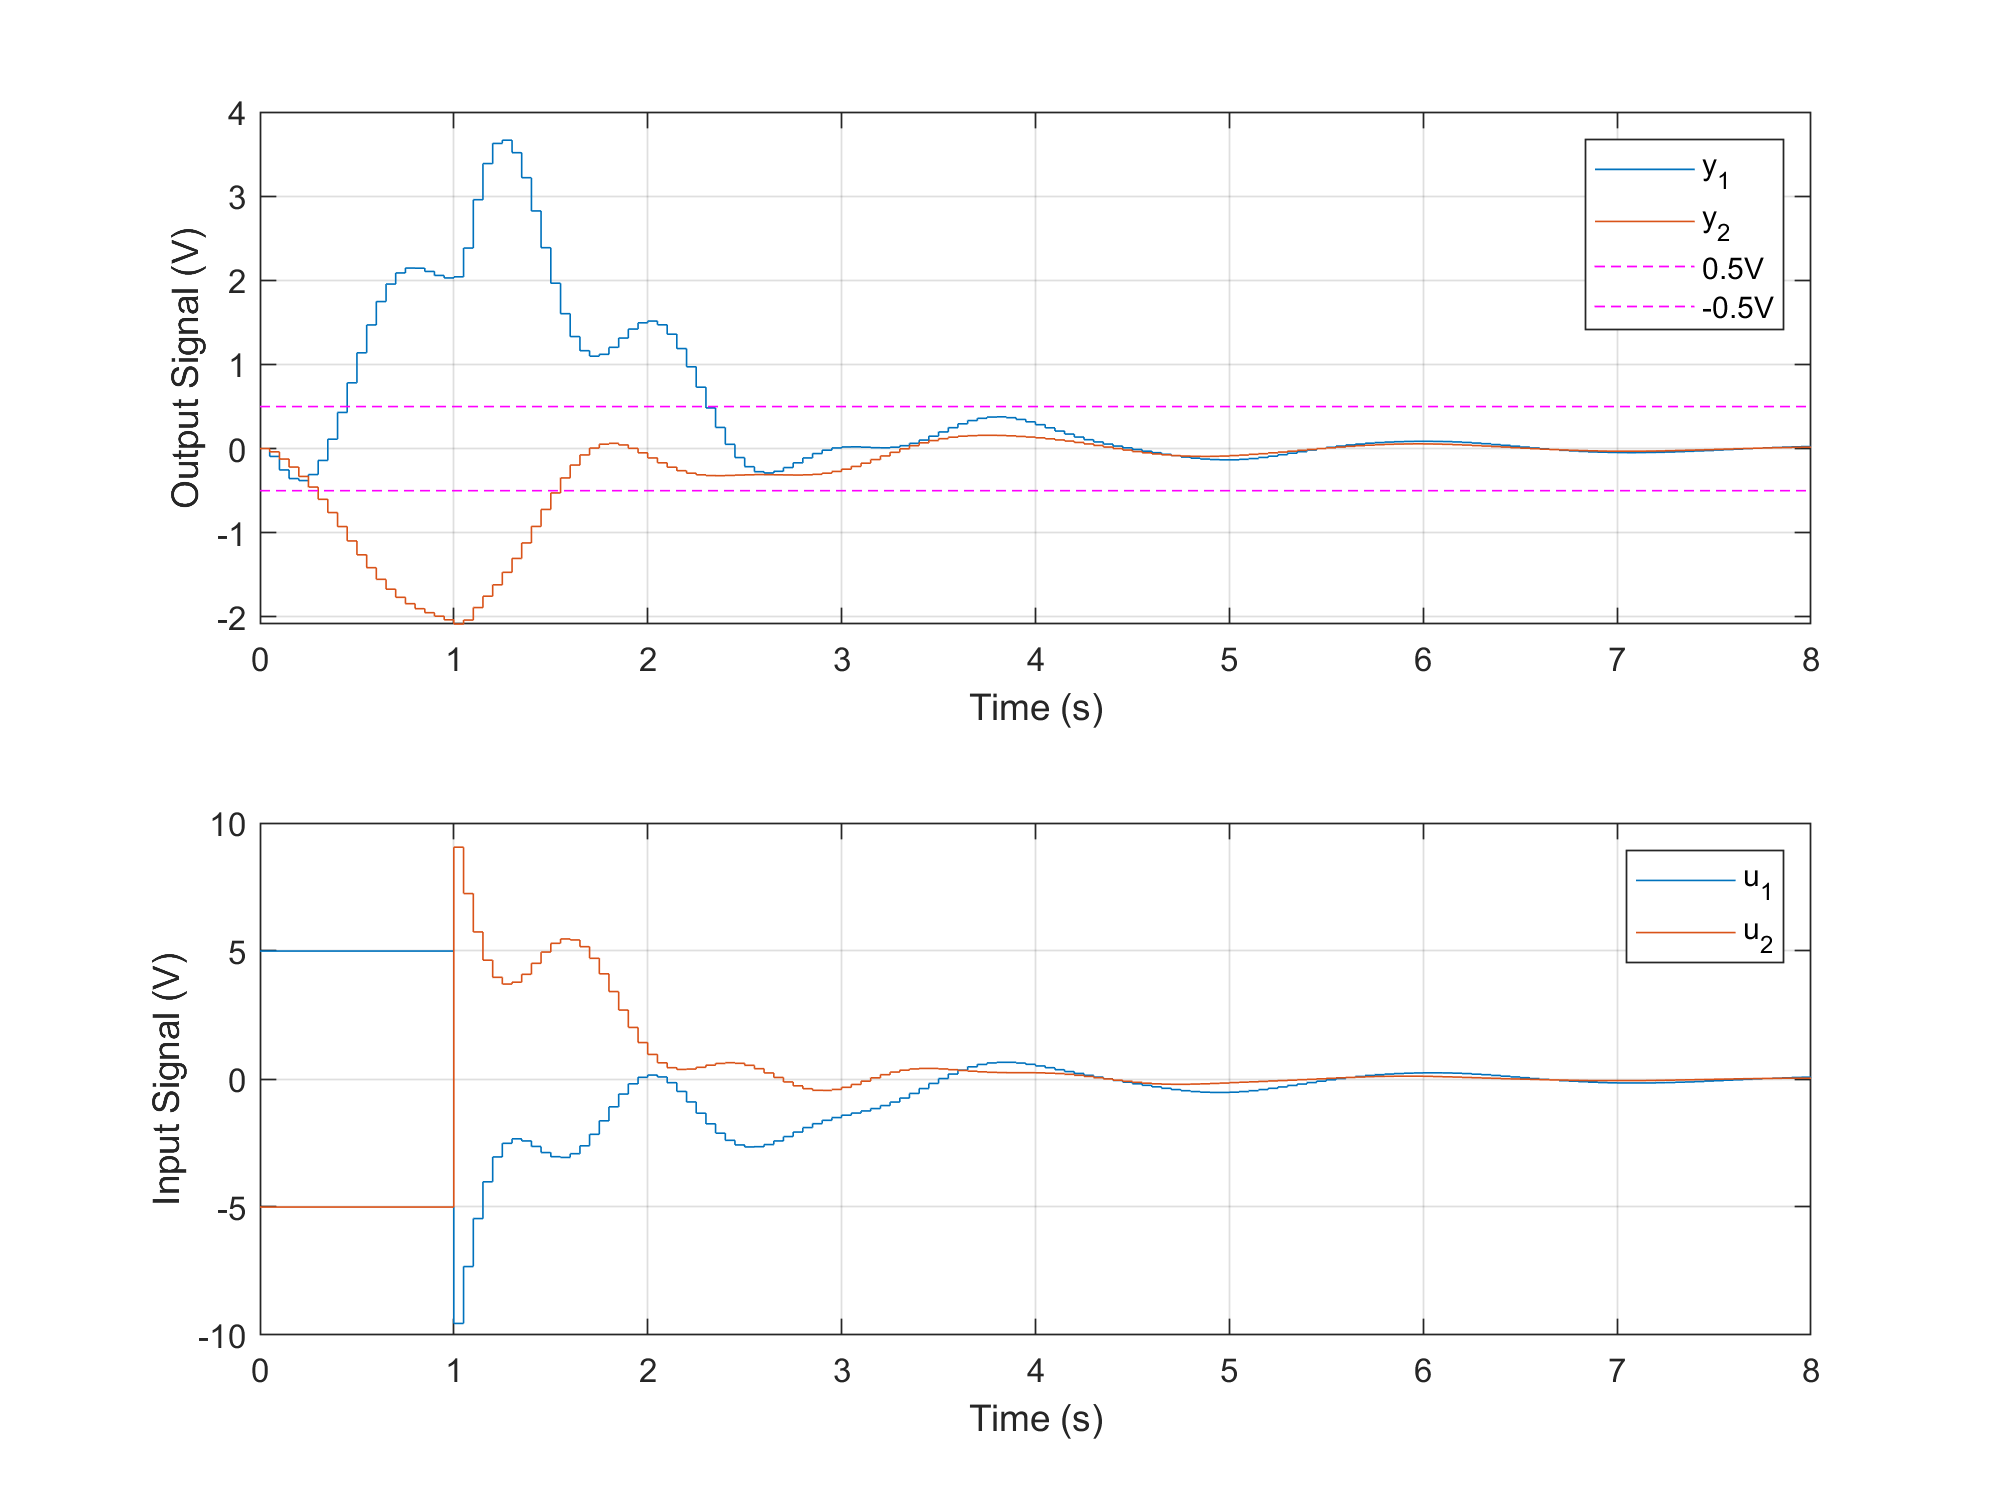

figure
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
subplot(2,1,1)
stairs(t,y')
line([0,t(end)],[0.5,0.5],'linestyle','--','color','m')
line([0,t(end)],[-0.5,-0.5],'linestyle','--','color','m')
grid on
ylabel('Output Signal (V)')
xlabel('Time (s)')
legend('y_1','y_2','0.5V','-0.5V')
subplot(2,1,2)
stairs(t,u')
grid on
ylabel('Input Signal (V)')
xlabel('Time (s)')
legend('u_1','u_2')
set(gcf,'Color','white')

## Section 4

Construct process noise covariance matrix.

assume there are process noise input in each of the two control input.

alpha =3E-3; %process noise tuing gain 
QN = alpha*eye(2);

Construct measurement noise covariance matrix.

N = 72000; % Number of sample
u00= [zeros(1,N);zeros(1,N)];
yn = s19_plant(u00);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b


RN = cov(yn(1,:),yn(2,:));

Cross covariance matrix between process noise and sensor noise.

Assume the sensor noise is uncorrelated with the process noise.

NN = zeros(2,2);

Output Kalman gain using the QR, RN and NN matrix.

[~,K] = kalman(dtss_fit,QN,RN,NN,'current'); 
disp('Kalman gain = ')

Kalman gain = 


disp(K)

    0.4051    0.4426
   -0.4467    0.5798
   -1.0459   -0.4032
    0.2731   -0.0521
    1.2660    0.0177
   -0.7717    0.5482



## Section 5

Define start and stop time of the simulation.

tstart = 1.0;  tfinal = 8.0;  time = [tstart, tfinal]; 

Construct output feedback control state space model.

Aofc = [dtss_fit.A - K * dtss_fit.C];
Bofc = [dtss_fit.B - K * dtss_fit.D, K];
Cofc = -G;
dt_ofc = ss(Aofc,Bofc,Cofc,[]);

Simulate closed loop response.

[y,u,xhat] = s19_plant(dt_ofc,time);

*** Warning *** s19_plant.p has only been tested on:
    R2017a, R2017b, R2018a, and R2018b


y_hat = dtss_fit.C * xhat + dtss_fit.D * u;

Plot the outputs, estimated outputs, error between two, and the control signals.

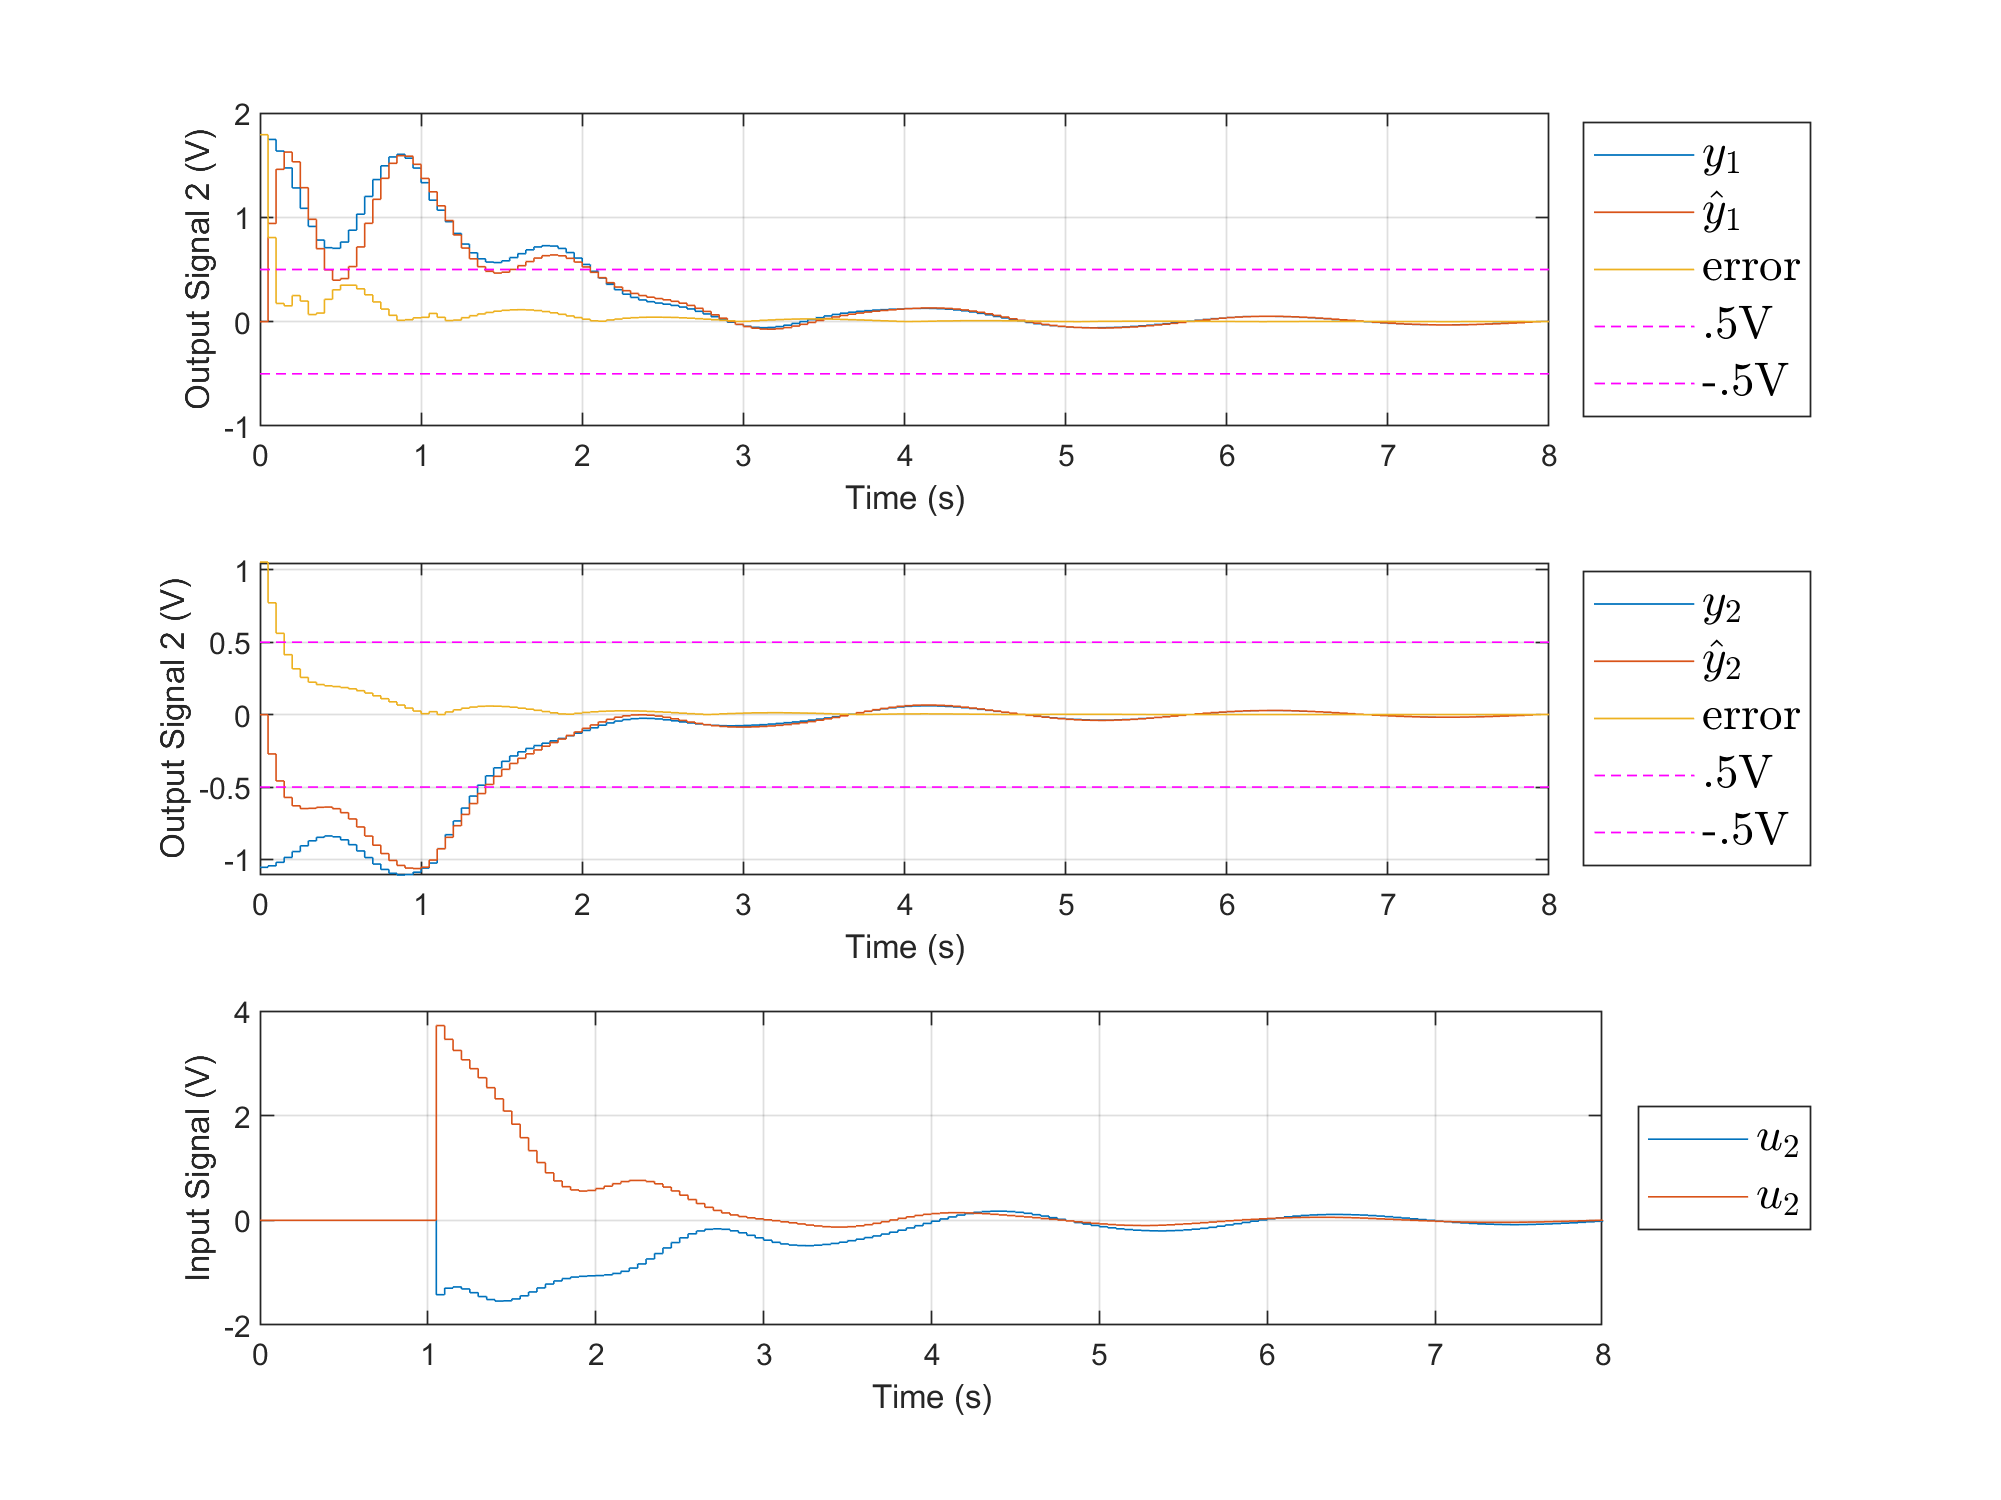

figure
set(gca,'fontsize',14) 
set(gcf,'Position',[0 0 800 600])
subplot(3,1,1)
stairs(t,y(1,:))
hold on
stairs(t,y_hat(1,:))
stairs(t,abs(y_hat(1,:)-y(1,:)))
line([0,t(end)],[0.5,0.5],'linestyle','--','color','m')
line([0,t(end)],[-0.5,-0.5],'linestyle','--','color','m')
grid on
ylabel('Output Signal 2 (V)')
xlabel('Time (s)')
legend({'$y_1$','$\hat{y}_1$','error','.5V','-.5V'},'Interpreter','latex','FontSize',14,'Location','Eastoutside')
subplot(3,1,2)
stairs(t,y(2,:))
hold on
stairs(t,y_hat(2,:))
stairs(t,abs(y_hat(2,:)-y(2,:)))
line([0,t(end)],[0.5,0.5],'linestyle','--','color','m')
line([0,t(end)],[-0.5,-0.5],'linestyle','--','color','m')
grid on
ylabel('Output Signal 2 (V)')
xlabel('Time (s)')
legend({'$y_2$','$\hat{y}_2$','error','.5V','-.5V'},'Interpreter','latex','FontSize',14,'Location','Eastoutside')
subplot(3,1,3)
stairs(t,u')
ylabel('Input Signal (V)')
xlabel('Time (s)')
grid on
set(gcf,'Color','white')
legend({'$u_2$','$u_2$'},'Interpreter','latex','FontSize',14,'Location','Eastoutside')